Подготовка к работе:

close all;
clear variables;

Загрузим данные из внешних файлов:

% cd ("Документы/Инженерка/2/");
spectra = importdata ("spectra.csv");
starNames = importdata ("star_names.csv");
lambdaStart = importdata ("lambda_start.csv");
lambdaDelta = importdata ("lambda_delta.csv");

Константы:

speedOfLight = 299792.458; % км / с
lambdaPr = 656.28; % нм

Определим необходимые величины:

[experiment_number, star_number] = size (spectra);
lambdaEnd = lambdaStart + (experiment_number - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

Подсчёт характеристик звезд:

[star_Ha, index_min] = min (spectra);
lambda_Ha = lambda (index_min);

z = (lambda_Ha / lambdaPr) - 1;
speed = z * speedOfLight;

Имена звёзд, удаляющихся от Земли:

movaway = starNames (speed > 0);

Построим график:

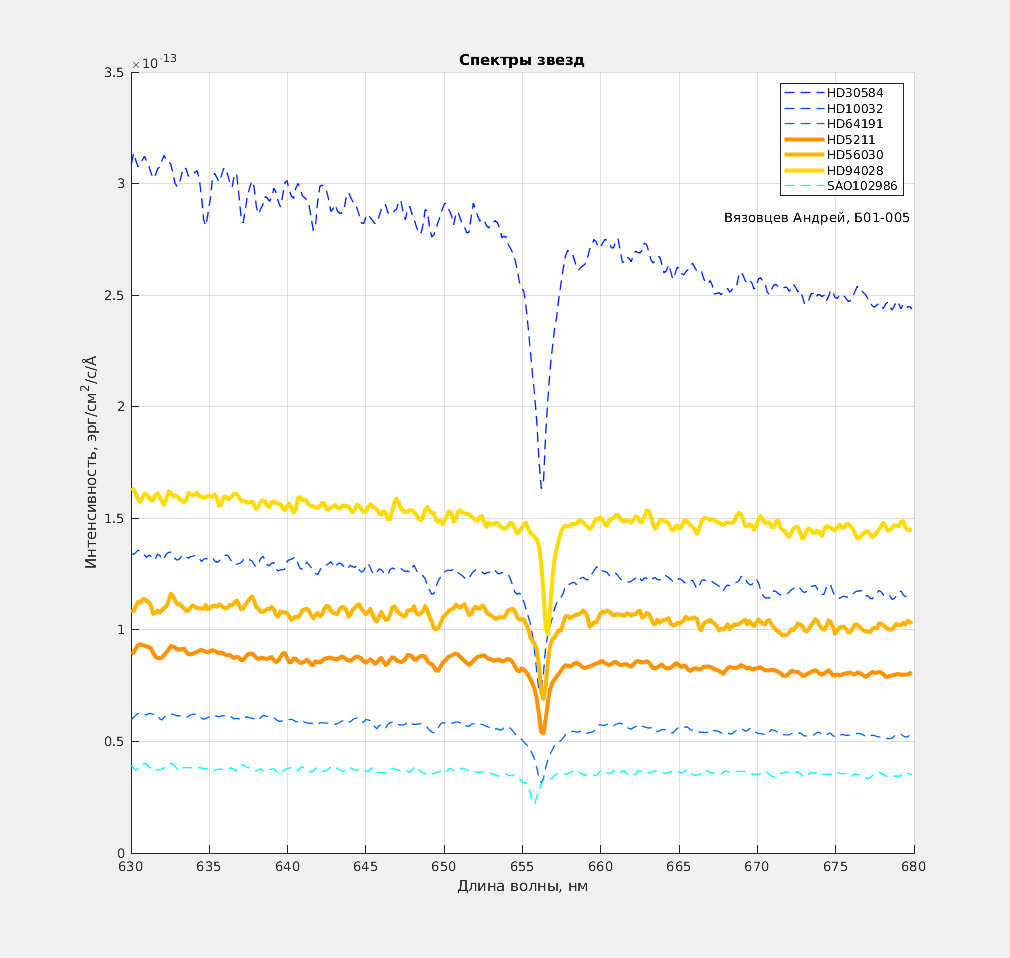

fig = figure;
set (fig, "Visible", "on");
set(fig, 'Position', [0 0 1000 1000]);

xlabel("Длина волны, нм");
ylabel(['Интенсивность, эрг/см^2/c/', char(197)]);
title("Спектры звезд");
text(lambdaEnd - 12, 2.85*10^(-13),"Вязовцев Андрей, Б01-005");

grid on;
hold on;

for i_star = 1.0 : star_number
    
    if speed (i_star) > 0
        plot (lambda, spectra(:, i_star),  "-", "LineWidth", 3, "Color", [1.0 (i_star / star_number) 0.0]);
    else
        plot (lambda, spectra(:, i_star), "--", "LineWidth", 1, "Color", [0.0 (i_star / star_number) 1.0]);
    end
end

legend(starNames);
saveas (fig, "StarsSpectra.png")